clc
clear, close all

% Load the folder content in a struct

% Load the folder with all the .txt files
textFiles = dir(strcat(pwd, '\*.txt'));
demographicsFile = (strcat(pwd, '\MCI Test Demographics (Responses).xlsx'));

demographics = readtable(demographicsFile);


% Save user info
users = struct;

% For every txt file in the folder
for iuser = 1 : size(textFiles, 1)
    fileID = fopen(textFiles(iuser).name);
    % Load in a cell the content separated by the semicolon
    C = textscan(fileID, '%s','Delimiter',';');
    fclose(fileID);


    idx = 1;
    usrIdx = 1;
    users(iuser).correct = 0; % Count the correct answers

    % Find the right ID from the demographics txt
    currentUserID = str2double(strsplit(textFiles(iuser, 1).name, '.'));
        
    for idxDemographics = 1 : size(demographics, 1)
        if table2array(demographics(idxDemographics, "PleaseInsertTheTESTIDNumberShownInTheLastPageOfTheTest_")) == currentUserID(1, 1)
            break;
        end
    end

    % Demographics
    users(iuser).timestamp = table2array(demographics(idxDemographics, "Timestamp"));
    users(iuser).ID = table2array(demographics(idxDemographics, "PleaseInsertTheTESTIDNumberShownInTheLastPageOfTheTest_"));
    users(iuser).age = table2array(demographics(idxDemographics,"HowOldAreYou_"));
    users(iuser).gender = table2array(demographics(idxDemographics, "WhatIsYourGender_"));
    users(iuser).musicExp = table2array(demographics(idxDemographics, "HowManyYearsOfMusicalExperienceDoYouHave_"));
    users(iuser).hearImp = table2array(demographics(idxDemographics, "DoYouHaveAnyHearingDisability_"));

    % For every rating report the answers divided in songs, mappings and rating
    while idx <= size(C{1,1}, 1)
        % Divide stimulus name to retrieve all information
        tmpStimuli = split(C{1, 1}{idx}, '_');
        users(iuser).semitones(usrIdx, :) = str2double(tmpStimuli{1, 1});
        users(iuser).contour(usrIdx, :) = string(tmpStimuli{2, 1});
        users(iuser).instrument(usrIdx, :) = string(tmpStimuli{3, 1});

        if size(tmpStimuli, 1) < 5
            % Discard the file extension
            tmpMapping = strsplit(tmpStimuli{4,1}, '.');
            users(iuser).mapping(usrIdx, :) = string(tmpMapping{1, 1});
        else

            % Discard the file extension
            tmpMapping = strsplit(tmpStimuli{5,1}, '.');
            users(iuser).mapping(usrIdx, :) = string(tmpMapping{1, 1});
        end

        % Store the answer associated to the stimuli
        idx = idx + 1; % The answer is stored in the next line
        users(iuser).answer(usrIdx, :) = string(C{1, 1}{idx});

        % If the answer matches the contour set a flag
        if users(iuser).contour(usrIdx, :) == users(iuser).answer(usrIdx, :)
            users(iuser).match(usrIdx, :) = true;
            users(iuser).correct = users(iuser).correct + 1;
        else
            users(iuser).match(usrIdx, :) = false;
        end

        % Update indexess
        idx = idx + 1;
        usrIdx = usrIdx +1;
    end
end

% Sort by musical experience
usersTable = struct2table(users);
sortedTable = sortrows(usersTable, 'musicExp');
users = table2struct(sortedTable)';

 

% Generate a masking plot accordingly to the selected values

Mappings on the haptuators:

filterData.am = true;
filterData.audio = true;
filterData.noHaptics = true;

Instruments:

filterData.viola = true;
filterData.piano = true;
filterData.clarinet = true;
filterData.sine  = true;

Distance between each note:

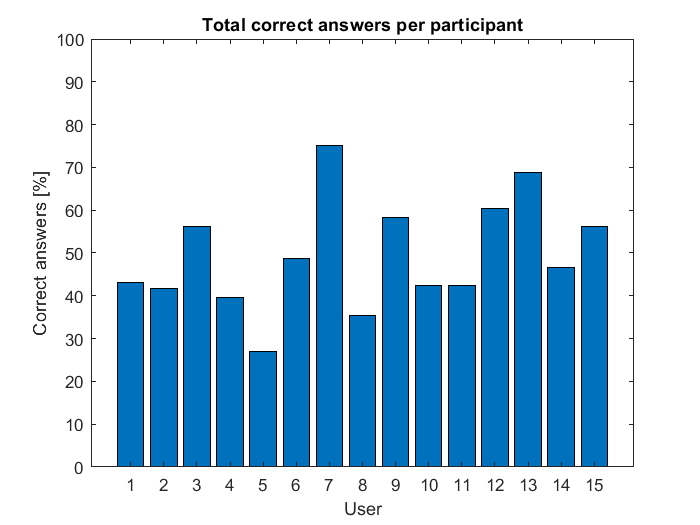

filterData.oneSemitone  = true;
filterData.twoSemitone  = true;

 

nUsers = size(users, 2);
plottingMaskMapping = zeros(size(users(1).answer, 1), size(users(1).answer, 2));
plottingMaskInstrument = zeros(size(users(1).answer, 1), size(users(1).answer, 2));
plottingMaskSemitone = zeros(size(users(1).answer, 1), size(users(1).answer, 2));

% Generate a masks for each category to plot the values
% Mappings
if filterData.am
    plottingMaskMapping = plottingMaskMapping | ...
        cell2mat(arrayfun(@(x)strcmp(x.mapping, 'CIAM'), users, 'UniformOutput', false));
end

if filterData.audio
    plottingMaskMapping = plottingMaskMapping |  ...
        cell2mat(arrayfun(@(x)strcmp(x.mapping, 'CI'), users, 'UniformOutput', false));
end

if filterData.noHaptics
    plottingMaskMapping = plottingMaskMapping |  ...
        cell2mat(arrayfun(@(x)strcmp(x.mapping, 'NoH'), users, 'UniformOutput', false));
end
% Instruments
if filterData.viola
    plottingMaskInstrument = plottingMaskInstrument |  ...
        cell2mat(arrayfun(@(x)strcmp(x.instrument, 'Viola'), users, 'UniformOutput', false));
end

if filterData.piano
    plottingMaskInstrument = plottingMaskInstrument |  ...
        cell2mat(arrayfun(@(x)strcmp(x.instrument, 'Piano'), users, 'UniformOutput', false));
end

if filterData.clarinet
    plottingMaskInstrument = plottingMaskInstrument |  ...
        cell2mat(arrayfun(@(x)strcmp(x.instrument, 'Clarinet'), users, 'UniformOutput', false));
end

if filterData.sine
    plottingMaskInstrument = plottingMaskInstrument |  ...
        cell2mat(arrayfun(@(x)strcmp(x.instrument, 'Sine'), users, 'UniformOutput', false));
end
% Semitones
if filterData.oneSemitone
    plottingMaskSemitone = plottingMaskSemitone |  ...
        cell2mat(arrayfun(@(x)(x.semitones == 1), users, 'UniformOutput', false));
end

if filterData.twoSemitone
    plottingMaskSemitone = plottingMaskSemitone |  ...
        cell2mat(arrayfun(@(x)(x.semitones == 2), users, 'UniformOutput', false));
end

% AND operation to intersecate the different masks and obtain the final
allPlottingMask = plottingMaskMapping & plottingMaskInstrument & plottingMaskSemitone;

% Apply the masks
% For every user in the folder
for iuser = 1 : size(textFiles, 1)

    % Generate the match with the filtered answers
    users(iuser).filteredMatch = users(iuser).match .* allPlottingMask(:, iuser);
    users(iuser).filteredCorrect = sum(users(iuser).filteredMatch);
    users(iuser).filteredPercentage = users(iuser).filteredCorrect ./...
        sum(allPlottingMask(:, iuser)) .* 100;
end

bar(vertcat(users.filteredPercentage))
ylabel('Correct answers [%]')
xlabel('User')
title('Total correct answers per participant')
ylim([0 100])

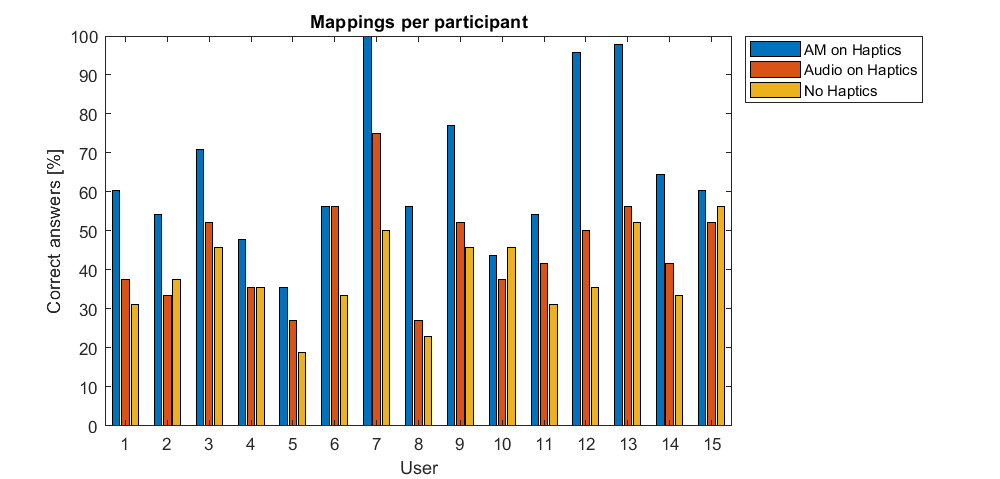


% For age plot
% yyaxis left
% b = bar(vertcat(users.filteredPercentage));
% ylabel('Correct answers [%]')
% yyaxis right
% p = plot(vertcat(users.musicExp), 'Marker', '.', 'LineStyle','--', 'MarkerSize', 10, 'LineWidth', 1);
% ylabel('Ages of musical experience')
% xlabel('User')
% title('Total correct answers per participant')
% ylim([0 30])

plottingMaskMappingAM = zeros(size(users(1).answer, 1), size(users(1).answer, 2));
plottingMaskMappingCI = zeros(size(users(1).answer, 1), size(users(1).answer, 2));
plottingMaskMappingNoH = zeros(size(users(1).answer, 1), size(users(1).answer, 2));

totAM = 0;
totCI = 0;
totNoH = 0;

plottingMaskMappingAM = plottingMaskMappingAM | ...
    cell2mat(arrayfun(@(x)strcmp(x.mapping, 'CIAM'), users, 'UniformOutput', false));

plottingMaskMappingCI = plottingMaskMappingCI |  ...
    cell2mat(arrayfun(@(x)strcmp(x.mapping, 'CI'), users, 'UniformOutput', false));


plottingMaskMappingNoH = plottingMaskMappingNoH |  ...
    cell2mat(arrayfun(@(x)strcmp(x.mapping, 'NoH'), users, 'UniformOutput', false));


% Apply the masks
% For every user in the folder
for iuser = 1 : size(textFiles, 1)

    % Generate the match with the filtered answers
    users(iuser).mappingAM = users(iuser).match .* plottingMaskMappingAM(:, iuser) .* plottingMaskInstrument(:, iuser) .* plottingMaskSemitone(:, iuser);
    users(iuser).mappingCI = users(iuser).match .* plottingMaskMappingCI(:, iuser) .* plottingMaskInstrument(:, iuser) .* plottingMaskSemitone(:, iuser);
    users(iuser).mappingNoH = users(iuser).match .* plottingMaskMappingNoH(:, iuser) .* plottingMaskInstrument(:, iuser) .* plottingMaskSemitone(:, iuser);
    
    users(iuser).AMFilteredPerc = sum(users(iuser).mappingAM) ./ ...
        (sum(plottingMaskInstrument(:, iuser) .* plottingMaskSemitone(:, iuser)) / 3) .* 100;
    users(iuser).CIFilteredPerc = sum(users(iuser).mappingCI) ./ ...
        (sum(plottingMaskInstrument(:, iuser) .* plottingMaskSemitone(:, iuser)) / 3) .* 100;
    users(iuser).NoHFilteredPerc = sum(users(iuser).mappingNoH) ./ ...
        (sum(plottingMaskInstrument(:, iuser) .* plottingMaskSemitone(:, iuser)) / 3) .* 100;
    
    totAM = totAM + users(iuser).AMFilteredPerc;
    totCI= totCI + users(iuser).CIFilteredPerc;
    totNoH = totNoH + users(iuser).NoHFilteredPerc;
end

totAM = totAM / nUsers;
totCI = totCI / nUsers;
totNoH = totNoH / nUsers;

x0 = 10;
y0 = 10;
widthGraph = 100 * nUsers;
heightGraph = 400;

if  false
    bar([1 : nUsers], [users.AMFilteredPerc; users.CIFilteredPerc; users.NoHFilteredPerc]', 'stacked')

else
    bar([1 : nUsers], [users.AMFilteredPerc; users.CIFilteredPerc; users.NoHFilteredPerc]')
end
set(gcf,'position', [x0,y0,widthGraph,heightGraph]);
lgd = legend('AM on Haptics', 'Audio on Haptics', 'No Haptics');
lgd.Location = 'northeastoutside';
ylabel('Correct answers [%]')
xlabel('User')
title('Mappings per participant')

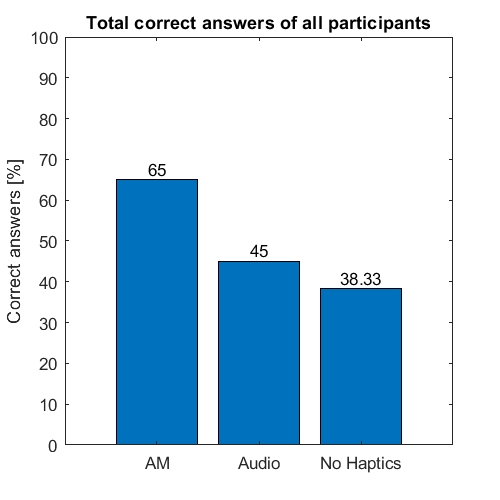



X = categorical({'AM','Audio','No Haptics'});
X = reordercats(X,{'AM','Audio','No Haptics'});
bTotGraph = bar(X, [totAM, totCI, totNoH]);
ylim([0 100])
set(gcf,'position', [x0,y0,400,heightGraph])
ylabel('Correct answers [%]')
title('Total correct answers of all participants')
xtips = bTotGraph(1).XEndPoints;
ytips = bTotGraph(1).YEndPoints;
labels = string(round(bTotGraph(1).YData, 2));
text(xtips, ytips , labels,'HorizontalAlignment','center',...
    'VerticalAlignment','bottom')

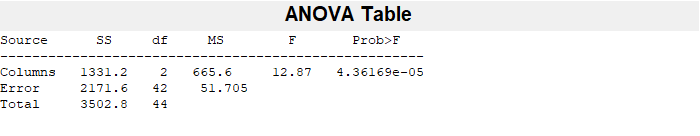

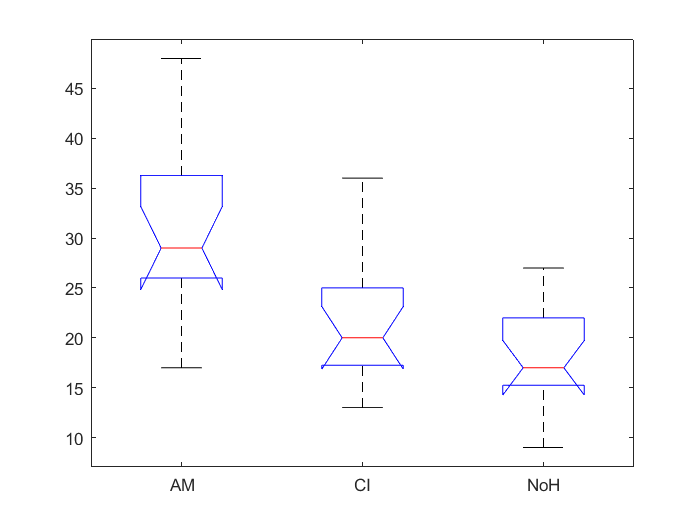

labels = {'AM', 'CI', 'NoH'};
AMScorePerUser = cell2mat(arrayfun(@(x)sum(x.mappingAM), users, 'UniformOutput', false))';
CIScorePerUser = cell2mat(arrayfun(@(x)sum(x.mappingCI), users, 'UniformOutput', false))';
NoHScorePerUser = cell2mat(arrayfun(@(x)sum(x.mappingNoH), users, 'UniformOutput', false))';

anova1([AMScorePerUser, CIScorePerUser, NoHScorePerUser], labels);

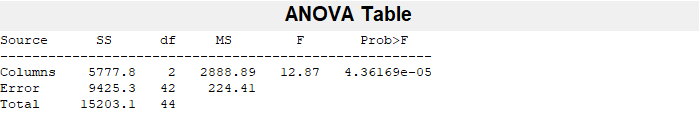



AMScorePerUserPerc = vertcat(users.AMFilteredPerc);
CIScorePerUserPerc = vertcat(users.CIFilteredPerc);
NoHScorePerUserPerc = vertcat(users.NoHFilteredPerc);

anova1([AMScorePerUserPerc, CIScorePerUserPerc, NoHScorePerUserPerc], labels);

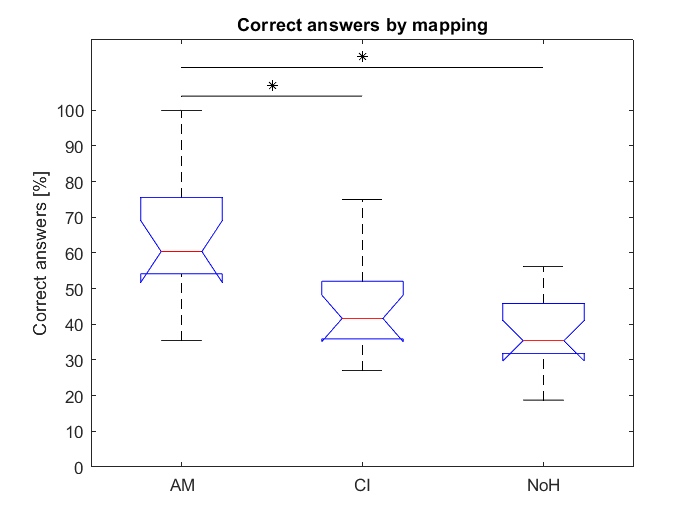

% ylim([0 100])
yt = get(gca, 'YTick');
axis([xlim    0  ceil(max(yt)*1.2)])
yticks([0 : 10 : 100])
xt = get(gca, 'XTick');
hold on
plot(xt([1 3]), [1 1]*max(yt)*1.12, '-k',  mean(xt([1 3])), max(yt)*1.15, '*k')
plot(xt([1 2]), [1 1]*max(yt)*1.04, '-k',  mean(xt([1 2])), max(yt)*1.07, '*k')
% plot(xt([2 3]), [1 1]*max(yt)*1., '-k',  mean(xt([2 3])), max(yt)*1.03, '*k')
hold off
title('Correct answers by mapping')
ylabel('Correct answers [%]')

T-test CI - NoH

[h,p,ci,stats] = ttest(CIScorePerUserPerc, NoHScorePerUserPerc)

h = 1

p = 0.0145

ci =     1.5404
   11.7929


stats = struct with fields:
    tstat: 2.7893
       df: 14
       sd: 9.2569


T-test AM - NoH

[h,p,ci,stats] = ttest(AMScorePerUserPerc, NoHScorePerUserPerc)

h = 1

p = 2.3873e-05

ci =    17.4143
   35.9190


stats = struct with fields:
    tstat: 6.1816
       df: 14
       sd: 16.7075


T-test AM - CI

[h,p,ci,stats] = ttest(AMScorePerUserPerc, CIScorePerUserPerc)

h = 1

p = 2.7834e-05

ci =    12.9579
   27.0421


stats = struct with fields:
    tstat: 6.0913
       df: 14
       sd: 12.7164


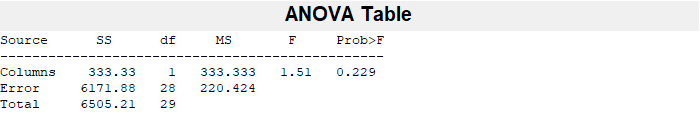

ans = 0.2290





diff_AM_NoH = vertcat(users.AMFilteredPerc) - vertcat(users.NoHFilteredPerc);


diff_AM_CI = vertcat(users.AMFilteredPerc) - vertcat(users.CIFilteredPerc);
anova1([diff_AM_CI, diff_AM_NoH], {'AM - CI', 'AM - NoH'})

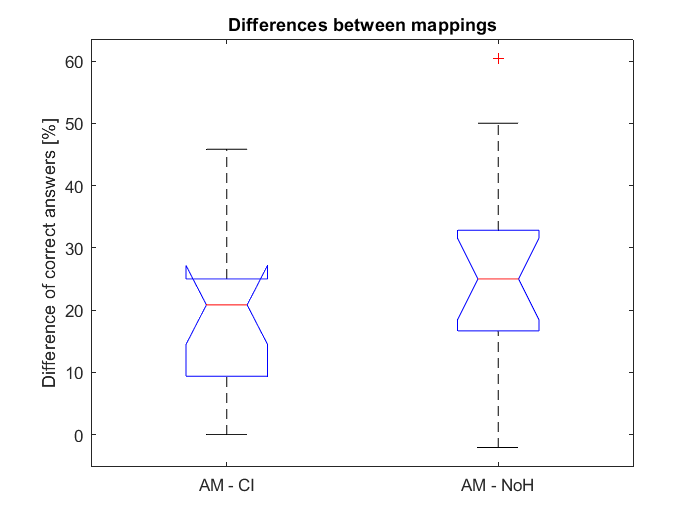

yticks([0 : 10 : 100])
ylabel('Difference of correct answers [%]')
title('Differences between mappings')